### A quick intro to Matlab before we start with statistics

% quick operations before we start
a = 10;
b = -20;

a + b

ans = -10

a - b * a

ans = 210

a / b

ans = -0.5000

### Some statistics functions

% create list of numbers from 0-100
data = [0:100];

% get the mean
mean(data)

ans = 50


% sum all the numbers
sum(data)

ans = 5050


% get the min and max number from the array
min(data)

ans = 0

max(data)

ans = 100

### Data Science 1: Is my data correct?

% unzip the dataset
unzip("archive.zip");

Dataset -- [https://www.kaggle.com/datasets/NUFORC/ufo-sightings?resource=download](https://www.kaggle.com/datasets/NUFORC/ufo-sightings?resource=download)

% read the dataset (do not use readmatrix)
ufo_dataset = readtable("complete.csv")

ufo_dataset = 88875×12 table
        datetime                  city                state        country         shape        duration_seconds_    duration_hours_min_                                                                               comments                                                                               datePosted    latitude    longitude      Var12   
    ________________    ________________________    __________    __________    ____________    _________________    ___________________    ____________________________________________________________________________________________________________________________________________________

Get rid of the column "var12"

ufo_dataset = removevars(ufo_dataset, {'Var12'})

ufo_dataset = 88875×11 table
        datetime                  city                state        country         shape        duration_seconds_    duration_hours_min_                                                                               comments                                                                               datePosted    latitude    longitude
    ________________    ________________________    __________    __________    ____________    _________________    ___________________    ______________________________________________________________________________________________________________________________________________________________    

Clean the data from ''

% count the missing data (let's see if we won't loose lots of data)
ufo_dataset.city

ans = 88875×1 cell array
    {'san marcos'                   }
    {'lackland afb'                 }
    {'chester (uk/england)'         }
    {'edna'                         }
    {'kaneohe'                      }
    {'bristol'                      }
    {'penarth (uk/wales)'           }
    {'norwalk'                      }
    {'pell city'                    }
    {'live oak'                     }
    {'hawthorne'                    }
    {'brevard'                      }
    {'bellmore'                     }
    {'manchester'                   }
    {'lexington'                    }
    {'harlan county'                }
    {'west bloomfield'              }
    {'niantic'                      }
    {'bermuda nas'                  }
    {'willow beach'                 }
    {'hudson'                       }
    {'cardiff (uk/wales)'           }
    {'hudson'                       }
    {'north charleston'             }
    {'washougal'                    }
    {'stoke mandeville (u


missing = 0;
variables = ufo_dataset.Properties.VariableNames;
for i = 1:numel(variables)
    if isnumeric(ufo_dataset.(variables{i}))
        missing = missing + sum(isnan(ufo_dataset.(variables{i})));
    else
        missing = missing + sum(ufo_dataset.(variables{i}) == "");
    end
end
missing

missing = 26823


% total
88875 * 12

ans = 1066500

Get rid of the missing data (it's just 10%)

% get rid of the missing data
ufo_dataset = rmmissing(ufo_dataset)

ufo_dataset = 68982×11 table
        datetime               city            state     country       shape        duration_seconds_    duration_hours_min_                                                                               comments                                                                               datePosted    latitude    longitude
    ________________    ___________________    ______    _______    ____________    _________________    ___________________    ______________________________________________________________________________________________________________________________________________________________    __________    <

### Visualizing our data

Let's take a look at:

- Scatter

- Histogram

- Heatmap    

#### Scatter:

%scatter(ufo_dataset, "country", "shape") %?? not working?

% Convert to categorical
countries = categorical(ufo_dataset.country);

Error using  .  (line 229)
Unrecognized table variable name 'country'.

shapes = categorical(ufo_dataset.shape);

% Convert to numeric codes for scatter
x = double(countries);
y = double(shapes);

scatter(x, y, 'filled')

% Fix axes with category labels
xticks(1:numel(categories(countries)))
xticklabels(categories(countries))

yticks(1:numel(categories(shapes)))
yticklabels(categories(shapes))

xlabel('Country')
ylabel('Shape')
title('UFO Sightings: Country vs Shape')

### Histogram

histogram(categorical(ufo_dataset.shape))
xlabel('UFO Shape')
ylabel('Number of sightings')
title('Distribution of UFO Shapes')

#### Heatmap

tbl = groupsummary(ufo_dataset, {'country','shape'});
heatmap(tbl, 'country', 'shape', 'ColorVariable', 'GroupCount')
title('UFO Sightings by Country and Shape')

#### Find correlations

corrcoef(ufo_dataset.duration_seconds_, ufo_dataset.shape) % correlation is basically 0

### Statistical modeling

We'll use this dataset: [https://www.kaggle.com/datasets/abhishek14398/salary-dataset-simple-linear-regression](https://www.kaggle.com/datasets/abhishek14398/salary-dataset-simple-linear-regression)

% unzip the dataset
unzip("archive (1).zip");
% read the dataset
salary_dataset = readtable("Salary_dataset.csv");

Get rid of Var1, it seems to be the index

%salary_dataset = removevars(salary_dataset, {"Var1"})

Check the correlation of Data

corrcoef(salary_dataset.YearsExperience, salary_dataset.Salary)

ans =     1.0000    0.9782
    0.9782    1.0000


Let's see if Scatter does something interesting

scatter(salary_dataset.YearsExperience, salary_dataset.Salary, "filled")
xlabel("Years of Experience")
ylabel("Salary")
title("Experience vs Salary")

What happens if we plot Time Series

plot(salary_dataset.YearsExperience, salary_dataset.Salary)

% add some moving average
smoothed_salary = movmean(salary_dataset.Salary, 5); % 5-point moving average
plot(salary_dataset.YearsExperience, salary_dataset.Salary, 'o') % raw data
hold on
plot(salary_dataset.YearsExperience, smoothed_salary, 'LineWidth',2)
xlabel('Experience (years)')
ylabel('Salary')
legend("Scatter",'Time Series','Moving Average')
title('Salary vs Experience with Moving Average')

What about adding some more insight, like some linear regression?

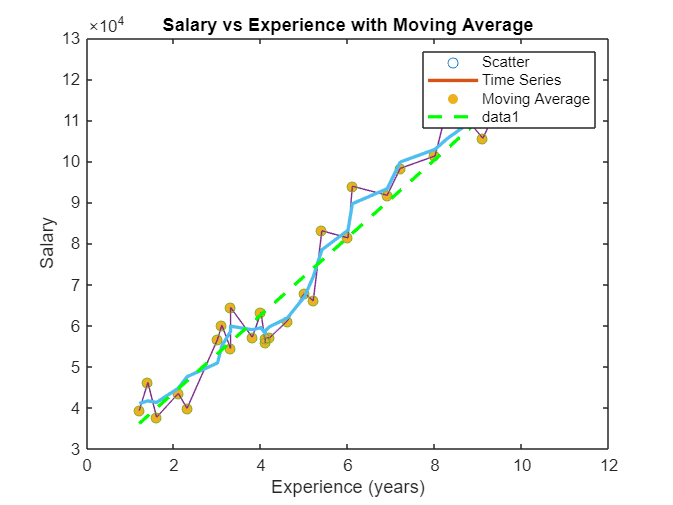

p = polyfit(salary_dataset.YearsExperience, salary_dataset.Salary, 1);
reg_line = polyval(p, salary_dataset.YearsExperience);
plot(salary_dataset.YearsExperience, reg_line, 'g--', 'LineWidth', 2)

### Probability and Distributions

Dataset to be used: [http://kaggle.com/datasets/yasserh/song-popularity-dataset](http://kaggle.com/datasets/yasserh/song-popularity-dataset) 

% unzip the dataset
unzip("archive (2).zip");
% read the dataset
spoti_dataset = readtable("song_data.csv");

Check the datset

spoti_dataset

spoti_dataset = 18835×15 table
              song_name               song_popularity    song_duration_ms    acousticness    danceability    energy    instrumentalness    key    liveness    loudness    audio_mode    speechiness    tempo     time_signature    audio_valence
    ______________________________    _______________    ________________    ____________    ____________    ______    ________________    ___    ________    ________    __________    ___________    ______    ______________    

Check histogram of songs duration (check which ones are between 2-5 mins)

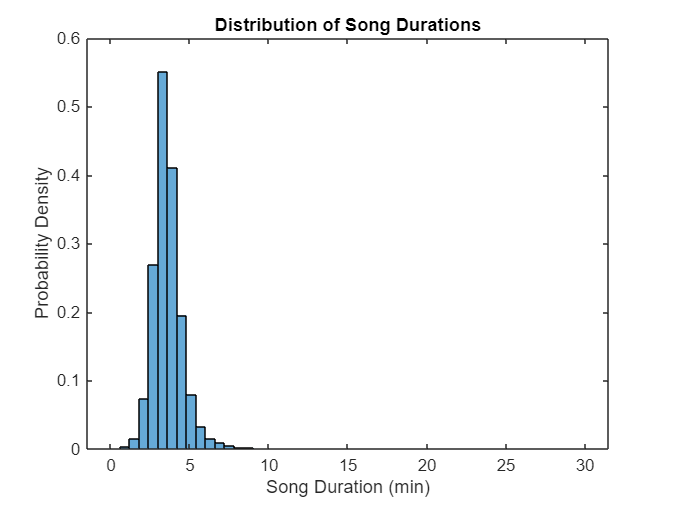

histogram(spoti_dataset.song_duration_ms/60000, 50,'Normalization','pdf') % minutes
xlabel('Song Duration (min)'), ylabel('Probability Density')
title('Distribution of Song Durations')

Monte Carlo Simulation:

It’s a method that uses **random sampling** to approximate answers to problems that are:

- **Too complex to solve analytically**, or

- **Don’t have a neat formula**.

Instead of calculating exact probabilities, you **simulate many random scenarios** and see how often an event occurs.

% take song durations in minutes
sim_durations = randsample(spoti_dataset.song_duration_ms/60000, 10000, true);
% reshape into columns of 5 songs each
playlist = sum(reshape(sim_durations,5,[]))

playlist =    20.7534   18.2973   20.2446   21.6027   19.0401   17.0487   17.7242   18.1851   16.8891   20.0374   18.4540   19.3229   18.5067   19.7391   17.5165   18.4047   20.9606   16.6932   19.4994   16.1153   17.6356   18.6273   16.1549   15.7984   15.8732   13.6284   15.3291   15.8670   20.8977   18.1850   15.3548   20.6025   17.3084   18.6735   17.9360   15.1282   20.0635   17.0788   16.4648   16.7340   20.3818   15.0517   18.2951   15.2803   17.3087   15.3270   16.2493   18.8011   15.7172   17.7349


% What is the probability that a random 5-song playlist lasts more than 20 minutes?
P = mean(playlist > 20)

P = 0.1695